# Flight Path Optimization

This script demonstrates the use of Optimization Toolbox™ to solve a simple pathfinding problem. 

We are given an airplane with a fixed airspeed and a vector field of wind in which to navigate. The objective is to find the path which minimizes the time taken to travel from the starting point to the finish point.

We can also find the optimal path when an initial wind field evolves to a second wind field. We navigate by recomputing the path at each time step to account for the time-varying wind field.

## Set parameters

clc
clear all
close all

AirSpeed = 500;
sizeX = 50;
sizeY = 25;
numWayPoints = 5;
randomSeed = 50;
rng(randomSeed);
method ="pchip" ; % Interpolation method
integrationFineness = 101;

% define zones
a = [10 40]; 
b = [5 20];
r = [5 5];

Specify the x values for the way points

x_vals = linspace(1,numWayPoints, numWayPoints).*(sizeX/(numWayPoints+1))

x_vals =     8.3333   16.6667   25.0000   33.3333   41.6667


## Fixed Wind Field

### Generate a random wind field

pathAxes = axes;
W_x = makeWindFun(sizeX,sizeY);
W_y = makeWindFun(sizeX,sizeY);
[Xgrid,Ygrid] = meshgrid(0:sizeX,0:sizeY);
hq = quiver(pathAxes,Xgrid,Ygrid,W_x,W_y,"k");

hold(pathAxes,"on");

pathAxes.XLabel.String = "Units = 100 [km]";
pathAxes.XLim = [0 sizeX];
pathAxes.YLim = [0 sizeY];
pathAxes.DataAspectRatio = [1 1 1];

plot(pathAxes,[0 sizeX],[sizeY sizeY]/2,"k.","MarkerSize",16)

Add some color to make it more visible by generating an image from the favorability of the wind to use as the background.

L = (sqrt((Xgrid-sizeX).^2 + (Ygrid-sizeY/2).^2));
Favorability = ((sizeX-Xgrid).*W_x +  (sizeY/2-Ygrid).*W_y)./L;
Favorability(~isfinite(Favorability)) = 0;

h_im = imagesc(pathAxes,Favorability);
set(h_im,"Xdata",[0 sizeX],"Ydata",[0 sizeY]);
uistack(h_im,"bottom");

Change the colormap.

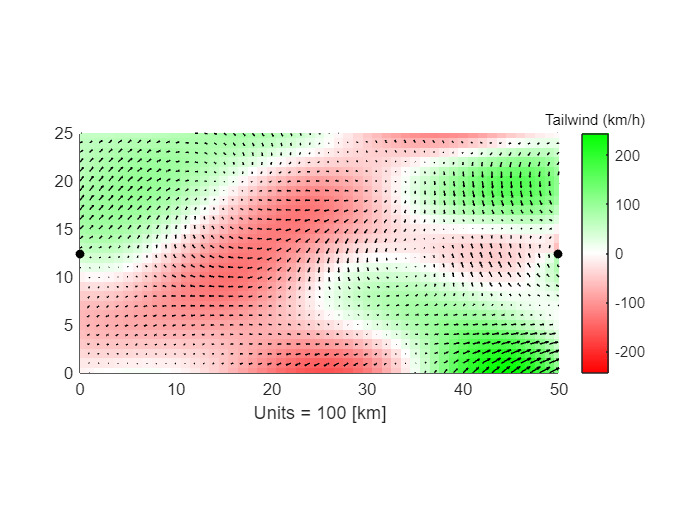

colormap(pathAxes,interp1([0,1,2],[1 0 0; 1 1 1; 0 1 0],0:0.01:2));
caxis(pathAxes,max(abs(Favorability(:)))*[-1 1]);

h_colorbar = colorbar(pathAxes);
title(h_colorbar,"Tailwind (km/h)")

### Generate waypoints in a straight line

Generate the points and plot.

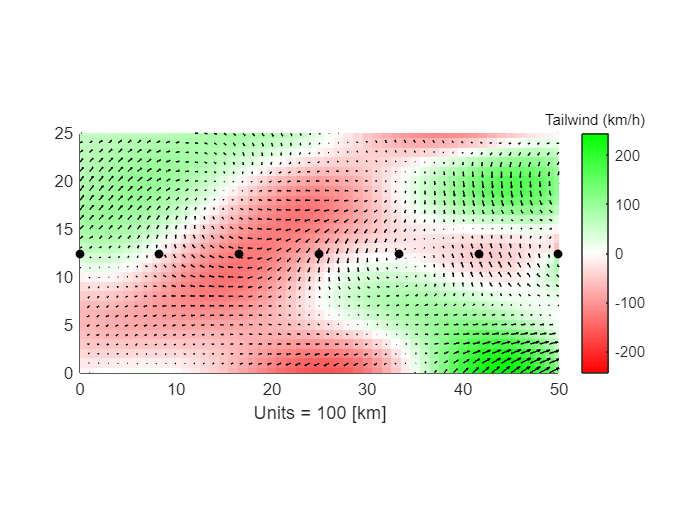

xWayPoints = linspace(0,sizeX,numWayPoints+2)';
yWayPoints = sizeY/2 * ones(numWayPoints+2,1);

h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the points

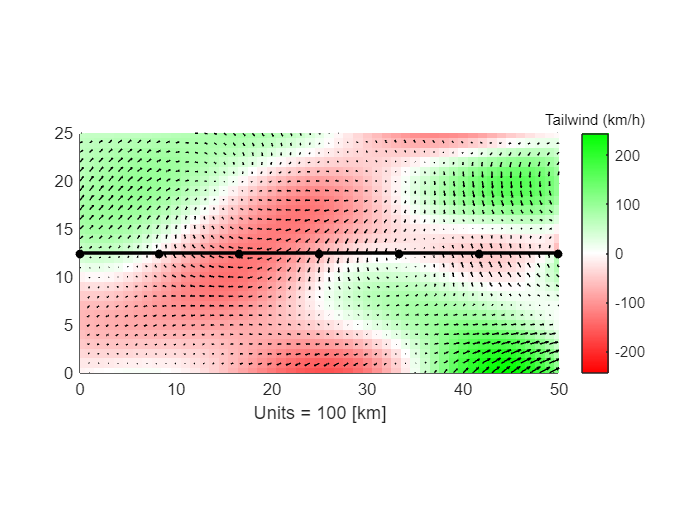

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

straightLineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);

% Display in Hours/Minutes
fprintf("Straight Line Travel Time: %d hours, %.1f minutes\n",floor(straightLineTime),rem(straightLineTime,1)*60);

Straight Line Travel Time: 10 hours, 58.8 minutes


### Generate randomly chosen waypoints

xWayPoints = linspace(0,sizeX,numWayPoints+2)' .* (1+0.05*randn(size(xWayPoints)));
yWayPoints = sizeY/2 + (0.1*sizeY*randn(numWayPoints+2,1));
xWayPoints([1 end]) = [0 sizeX];
yWayPoints([1 end]) = sizeY/2;

Plot them

delete([h_wp h_path]);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

Generate a continuous path from the waypoints

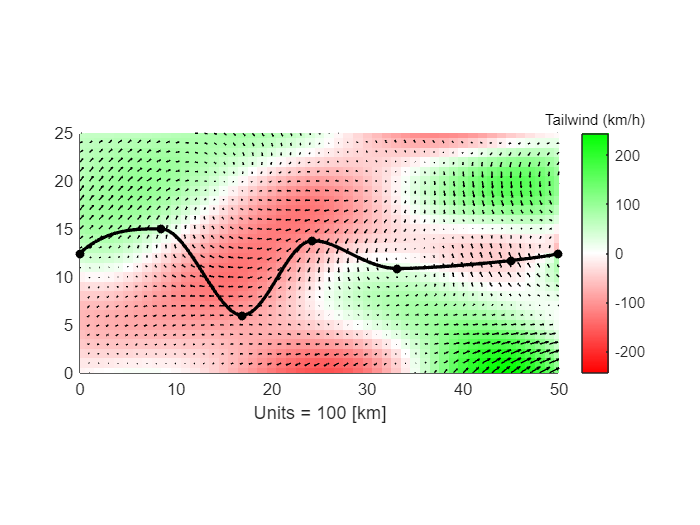

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

Calculate the time taken

lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);
fprintf("Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

Travel Time: 12 hours, 48.8 minutes


### Find an optimal path using `fmincon`

Find the optimal waypoints. Define the objective function to minimize the time take on the path interpolated from the waypoints. 

%objectiveFun = @(P) getTimeFromPath(P,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness);

%objectiveFun_test = @(P) DistanceCalc(P,a,b);

FPP_fitness_function = @(P) GA_Fitness_Func_FPP(P,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness,a,b,r, x_vals);

Set optimization options

options = optimoptions('ga');
options = optimoptions(options,'MaxGenerations', 25);
options = optimoptions(options,'CreationFcn', @gacreationuniform);
options = optimoptions(options,'CrossoverFcn', @crossoverscattered);
options = optimoptions(options,'MutationFcn', {  @mutationuniform [] });
%options = optimoptions(options,'Display', 'iter');
options = optimoptions(options,'MaxStallGenerations', 40);
%options = optimoptions(options, 'PlotFcn', @gaplotbestf);
options = optimoptions(options,'Vectorized', 'on')

options =   ga options:

   Set properties:
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
                  MaxGenerations: 25
             MaxStallGenerations: 40
                     MutationFcn: {@mutationuniform  []}
                   UseVectorized: 1

   Default properties:
             ConstraintTolerance: 1.0000e-03
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                    MaxStallTime: Inf
                         MaxTime: Inf
    NonlinearConstrain

options = optimoptions(options,'PopulationSize', 300);

Specify lower and upper bounds on the waypoints.

lb = zeros(1,numWayPoints);
ub = ones(1,numWayPoints)*sizeY;

Do the optimization

optimalWayPoints = ga(FPP_fitness_function,5,[],[],[],[],lb,ub,[],options);

Optimization terminated: maximum number of generations exceeded.


optimalWayPoints = [x_vals', optimalWayPoints'];
optimalWayPoints = [0 sizeY/2; optimalWayPoints; sizeX sizeY/2];

### Plot the optimal solution

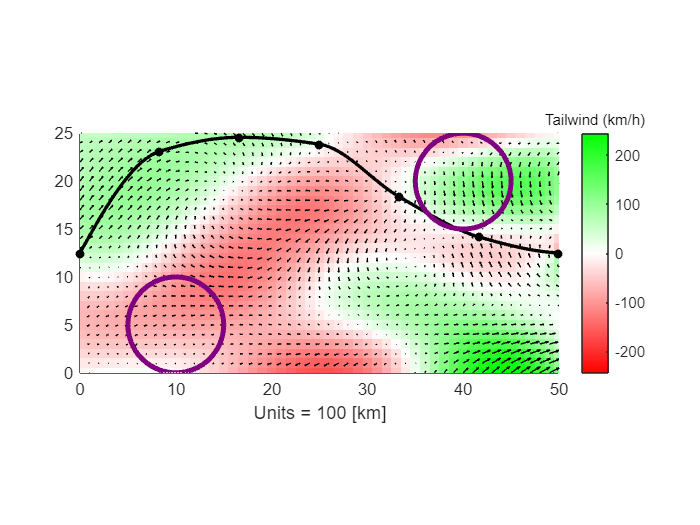

delete([h_wp h_path]);

xWayPoints = optimalWayPoints(:,1);
yWayPoints = optimalWayPoints(:,2);
h_wp = plot(pathAxes,xWayPoints,yWayPoints,"Color","k","LineStyle","none","Marker",".","MarkerSize",16);

pathPoints = waypointsToPath([xWayPoints,yWayPoints],method,sizeX,sizeY,integrationFineness);
h_path = plot(pathAxes,pathPoints(:,1),pathPoints(:,2),"k","LineWidth",2);

% Define the coordinates and radius of the circles
x1 = a(1);
y1 = b(1);
r1 = r(1);
x2 = a(2);
y2 = b(2);
r2 = r(2);

% Plot the circles
th = 0:pi/50:2*pi;
xunit1 = r1 * cos(th) + x1;
yunit1 = r1 * sin(th) + y1;
xunit2 = r2 * cos(th) + x2;
yunit2 = r2 * sin(th) + y2;
plot(xunit1, yunit1, 'LineWidth', 3, 'Color', '#800080');
hold on;
plot(xunit2, yunit2, 'LineWidth', 3, 'Color', '#800080');

lineTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed);
fprintf("Optimal Travel Time: %d hours, %.1f minutes\n",floor(lineTime),rem(lineTime,1)*60);

Optimal Travel Time: 11 hours, 0.1 minutes



%DistanceCalc(P,a,b);

## Helper Functions

### makeWindFun

function iWind = makeWindFun(SZX,SZY)
% This is just a helper function to make a random scalar function. This is
% called twice to generate a random wind field.

windFineness = 0.1;
if ~exist("SZX","var")
    SZX = 50;
    SZY = 50;
end

N = 50; % Various parameters used in generating a random "smooth" matrix
NL = 40;
NP = 500;
rx = randn(NL,N);
rx = interpft(rx,NP);
ry = randn(NL,N);
ry = interpft(ry,NP);
I = (rx*ry');

[xgi,ygi] = meshgrid(linspace(1,2 + 498*windFineness,SZX+1),linspace(1,2 + 498*windFineness,SZY+1));
iWind = 10*interp2(1:500,1:500,I,xgi,ygi);
end

### waypointsToPath

function pathPoints = waypointsToPath(p,method,sizeX,sizeY,fineness)
% Interpolate the curve based on the discrete waypoints to generate a
% continuous path.

nP = size(p,1);
pathPoints = [interp1(1:nP,p(:,1),linspace(1,nP,fineness)',method,"extrap") ...
    interp1(1:nP,p(:,2),linspace(1,nP,fineness)',method,"extrap")];

% Do not leave the box
pathPoints(:,1) = min(pathPoints(:,1),sizeX);
pathPoints(:,1) = max(pathPoints(:,1),0);
pathPoints(:,2) = min(pathPoints(:,2),sizeY);
pathPoints(:,2) = max(pathPoints(:,2),0);
end

### getTimeFromPath

function travelTime = getTimeFromPath(pathPoints,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This is the main function that actually calculates the line integral
% along the path. This is the objective function for the optimizer.

% If we are called from the optimization routine (caller = "optimizer")
% then we need to interpolate the fine path from the input control points.
if isvector(pathPoints)
    pathPoints = [0 sizeY/2; pathPoints; sizeX sizeY/2];
    pathPoints = waypointsToPath(pathPoints,method,sizeX,sizeY,integrationFineness);
end

dP = diff(pathPoints);

% Interpolate the wind vector field at all the points in pathPoints.
V_wind = [interp2(W_x,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear") ...
    interp2(W_y,pathPoints(1:end-1,1)+1,pathPoints(1:end-1,2)+1,"linear")];

% Dot product the wind (V_wind) with the direction vector (dP) to get
% the tailwind/headwind contribution
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));
dx = sqrt(sum(dP.^2,2))*100; %dx is the length of each subinterval in pathPoints
dt = dx./(AirSpeed+V_add);  %dT = dP/dV
travelTime = sum(dt);
end

### calculateTimeIntermediate

function totalTime = calculateTimeIntermediate(x,W_x,W_y,x0,y0,AirSpeed,sizeX,sizeY,method,integrationFineness)
% This calculates the time starting from a specified start point (x0,y0)
% It is used in the time-dependent version of this optimization problem.

L = numel(x);
X_points = linspace(x0,sizeX,L+2)';

points = [X_points [y0; x; sizeY/2]];

PointList = [interp1(X_points,points(:,1),linspace(x0,sizeX,integrationFineness)',method,"extrap") ...
    interp1(X_points,points(:,2),linspace(x0,sizeX,integrationFineness)',method,"extrap")];

PointList(PointList < 0) = 0;
PointList(:,1) = min(PointList(:,1),sizeX);
PointList(:,2) = min(PointList(:,2),sizeY);

dP = diff(PointList);

V_wind = [interp2(W_x,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")...
    interp2(W_y,PointList(1:end-1,1)+1,PointList(1:end-1,2)+1,"linear")];

% Dot product the wind (V_wind) with the direction vector (dP)
V_add = (sum(V_wind.*dP,2))./sqrt(sum(dP.^2,2));

dx = sqrt(sum(dP.^2,2)); % dx is the length of each subinterval in plist
dT = dx./(AirSpeed+V_add);  % dT = dP/dV
totalTime = 100*sum(dT);
end

## Objects Distance Calculation

function TooClose = DistanceCalc(P,a,b)

% P - legnth of 10
reshaped_P = P;

% initialize distsance storage array
distance_sum = zeros(size(reshaped_P,1),size(a,2));

for i = 1:size(reshaped_P,1)

    for j = 1:size(a,2)

            distance_sum(i,j) = (reshaped_P(i,1)-a(:,j))^2 + (reshaped_P(i,2)-b(:,j))^2;

    end

end

TooClose = sum(sum(distance_sum));

end


**Constraint Function**

function distance_sum = zone_distance(P, a, b, r)

% P - legnth of 10
reshaped_P = P;

% initialize distsance storage array
distance_sum = zeros(size(reshaped_P,1),size(a,2));

    for i = 1:size(reshaped_P,1)
    
        for j = 1:size(a,2)
    
                distance_sum(i,j) = -1*(((reshaped_P(i,1)-a(:,j))^2 + (reshaped_P(i,2)-b(:,j))^2) - (r(j)^2));
    
        end
    
    
    end

end


**MOGA FITNESS CALCULATION **

function final_population_fitness = GA_Fitness_Func_FPP(P,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness,a,b,r,x_vals)


% This function calculates the multi-objective, constraint adusted fitness
% of a population of candidate solutions

% INPUTS: 
% X - Matlab generated population of candidate designs (with length n -
% number of design variables)

% OUTPUTS:
% final_population_fitness - vector of fitness values for each member of
% the generated population

% PROCEDURE:
% 1. calculate objective function value(s) for each member of population
% 2. calculate fronts for population
% 3. calculate adjueted fitness for each population member (nc, etc)
% 4. calculate constraint adjusted fitness

% Documentation: framerwork was inspired from Dr. Aute's GA code

    % determine the number of designs in the population
    NumDesign = size(P, 1);
    
    global gen
    
    % Initialize empty vector for objective function value storage
    % 2 coresponds to 2 objective functions for this problem
    population_objectives_vector = zeros(NumDesign,2);
    
    % R1 = penalty factor
    R1 = 100000;
    
    % CALCULATE THE INITIAL OBJECTIVE FUNCTION VALUES FOR EACH INDIVIDUAL
    % ix is the index for current design
    for ix = 1:NumDesign
    
        % pluck indiovidual dsign out of the population array
        x = P(ix,:);

        x = [x_vals', x'];
        
        % ---------- INITIAL OBJECTIVE FUNCTION VALUATION -------------------
    
        travelTime = getTimeFromPath(x,W_x,W_y,AirSpeed,sizeX,sizeY,method,integrationFineness);

        hazard_distance = DistanceCalc(x,a,b);
    
        % update fittness vector
        population_objectives_vector(ix,1) = travelTime;
        population_objectives_vector(ix,2) = -hazard_distance ;
    end

     % DETERMINE THE FRONTS OF THE POPULATION SET
    fronts = non_dominated_sort(population_objectives_vector);
    
    % CALCULATE THE ADJUSTED FITTNESS VALUES FOR EACH INDIVIDUAL
    [dist, niche, shared_fitness] = calc_rank_distances(P, population_objectives_vector, fronts, .75, 3, .25);
    
    % CONSTRAINT HANDELING
    % define empty array for storing constrain values:
    constrained_fitness = zeros(NumDesign,1);
    
    %tracking variable fon constraints:
    violation_tracker = zeros(NumDesign,1);

    for ix = 1:NumDesign
    
        % pluck indiovidual dsign out of the population array
        x = P(ix,:);

        x = [x_vals', x'];

        constraint_matrix = zone_distance(x, a, b, r);

        total_violation = 0;
    
        for j = 1:size(constraint_matrix,1)

             for k = 1:size(constraint_matrix,2)
    
                if constraint_matrix(j,k) > 0
        
                    total_violation = total_violation + constraint_matrix(j,k);
       
                end 
    
             end
        end 

        violation_tracker(ix,1) = total_violation;

        constrained_fitness(ix,1) = -1*(shared_fitness(ix,1)) + (total_violation * R1);
    end
    
    % define final population fitness storage vector:
    % Define final population fitness output vector:
    final_population_fitness = constrained_fitness;
    
    % ------------------ OUTPUT FORMARTTING ------------------------------
    % output population data to excel file:
    population_data = [P,population_objectives_vector, violation_tracker,final_population_fitness];
    filename = 'population_data_tracker.xlsx';
    writematrix(population_data,filename,'Sheet',1);
end